% Define transfer function
num = [1];
den = conv([1 0], [1 1 4]);
f = tf(num, den);

roots(den + num)

ans =   -0.3928 + 1.4756i
  -0.3928 - 1.4756i
  -0.2145 + 0.0000i


roots(den)

ans =    0.0000 + 0.0000i
  -0.5000 + 1.9365i
  -0.5000 - 1.9365i


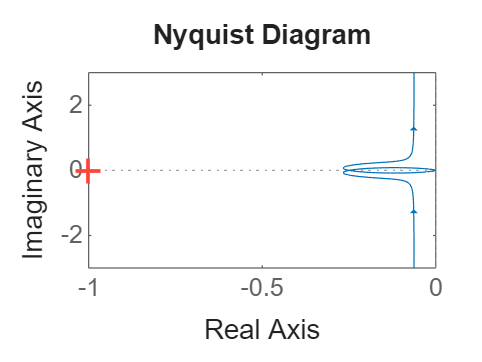


nyquist(f)



% Frequency range
w = -4:0.1:4;

% Evaluate frequency response
H = freqresp(f, w); 
H = squeeze(H);  % Ensure it's a 1D vector

% Create table
RePart = real(H);
ImPart = imag(H);

T = table(transpose(w), RePart, ImPart, ...
    'VariableNames', {'w', 'Re', 'Im'});

% Display table
disp(T)

     w          Re           Im    
    ____    __________    _________

      -4      -0.00625     -0.01875
    -3.9    -0.0070985    -0.020404
    -3.8    -0.0081015    -0.022258
    -3.7    -0.0092949    -0.024343
    -3.6     -0.010725    -0.026693
    -3.5     -0.012451     -0.02935
    -3.4     -0.014553    -0.032359
    -3.3     -0.017134    -0.035775
    -3.2     -0.020334    -0.039652
    -3.1     -0.024342     -0.04405
      -3     -0.029412     -0.04902
    -2.9     -0.035896    -0.054587
    -2.8     -0.044276    -0.060721
    -2.7     -0.055206    -0.067269
    -2.6     -0.069553    -0.073833
    -2.5     -0.088398    -0.079558
    -2.4       -0.1129    -0.082791
    -2.3       -0.1438    -0.080653
    -2.2      -0.18032    -0.068851
    -2.1      -0.21843    -0.042646
      -2         -0.25            0
    -1.9      -0.26581     0.054561
    -1.8      -0.26194       0.11